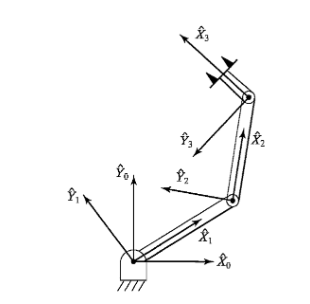

DH Parameters

L1 = 4;
L2 = 3;
L3 = 2;
m1 = 20;
m2 = 15;
m3 = 10;
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;


Set Geometry of Robot and mass Properties

dhparams = [L1 0 0 0;
        L2 0 0 0;
        L3 0 0 0;]

dhparams =      4     0     0     0
     3     0     0     0
     2     0     0     0



robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

body1.Joint = jnt1;
body1.Mass = m1;
body1.CenterOfMass = [L1/2 0 0];
body1.Inertia = [ 0 0 I1 0 0 0];
body2.Joint = jnt2;
body1.Mass = m2;
body1.CenterOfMass = [L2/2 0 0];
body1.Inertia = [ 0 0 I2 0 0 0];
body3.Joint = jnt3;
body1.Mass = m2;
body1.CenterOfMass = [L3/2 0 0];
body1.Inertia = [ 0 0 I3 0 0 0];

addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');


Do The forward dynamics

%Torques
tau1 = 20; %Nm
tau2 = 5;
tau3 = 1;
torques = [tau1 tau2 tau3];
%Initial Joint Positions
q1 = -pi/3; 
q2 = pi/2;
q3 = pi/6;
config = [q1 q2 q3];
%Iniitial Joint Velocities
w1 = 0; %rad/s
w2 = 0;
w3 = 0;
vels = [w1 w2 w3];


robot.DataFormat = 'row';
robot.Gravity = [0 -9.81 0];


No external Forces

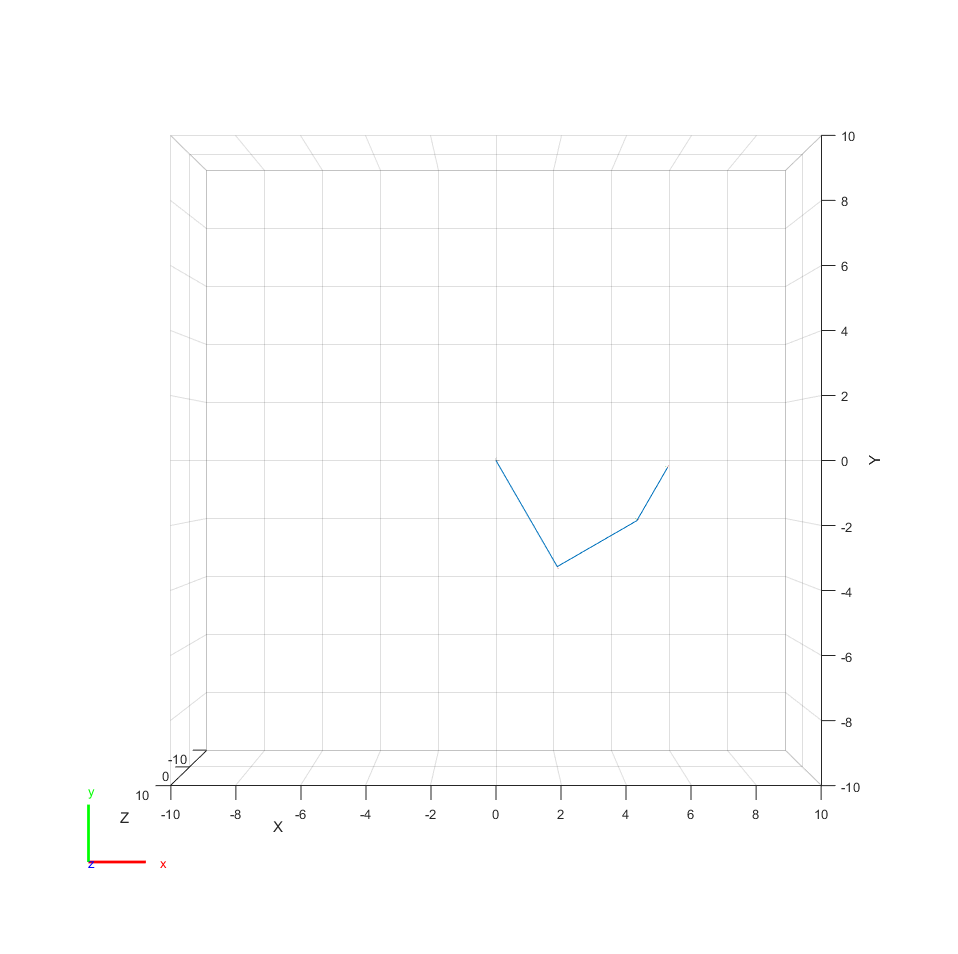

show(robot, config);
view(0,90);

qddot = forwardDynamics(robot, config, vels, torques)

qddot =    -0.9999   -1.4752    2.4854


With External Forces

wrench = [0 0 1 1 2 0];
fext = externalForce(robot,'body3',wrench,config)

fext =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0   11.1603   -1.2321    1.8660         0


show(robot, config);
view(0,90);

qddot = forwardDynamics(robot, config, vels, torques, fext)

qddot =    -0.9922   -1.3750    3.2716
